# Pulse detector test bench (step 1)

© 2019-2020 The MathWorks, Inc.

This test bench creates a reference pulse detection algorithm, simulates the Simulink model implementation, and compares the Simulink result to the MATLAB reference.

## Create reference algorithm & parameters

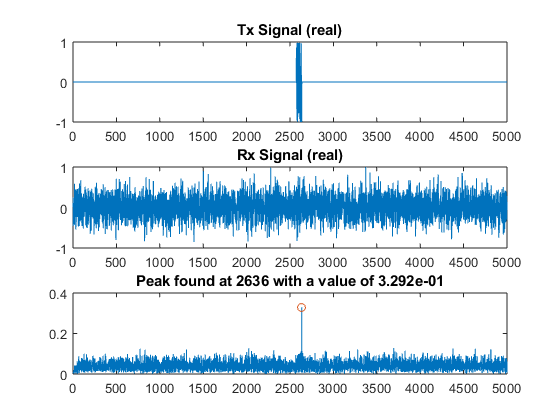

pulse_detector_reference;

## Simulate model and compare results to reference

if iscolumn(CorrFilter)
    CorrFilter = transpose(CorrFilter); % need row vector for filter block
end
SimTime = length(RxSignal) + WindowLen;

% Simulate model
slout = sim('pulse_detector_v1_1');

% Correlation filter output
FilterOutSL = getLogged(slout,'filter_out');
compareData(real(FilterOut),real(FilterOutSL),{2 3 1},'ML vs SL correlator output (re)');


Maximum error for ML vs SL correlator output (re) out of 5000 values
 2.220446e-16 (absolute), 6.751916e-14 (percentage)


compareData(imag(FilterOut),imag(FilterOutSL),{2 3 2},'ML vs SL correlator output (im)');


Maximum error for ML vs SL correlator output (im) out of 5000 values
 9.714451e-17 (absolute), 7.651092e-14 (percentage)


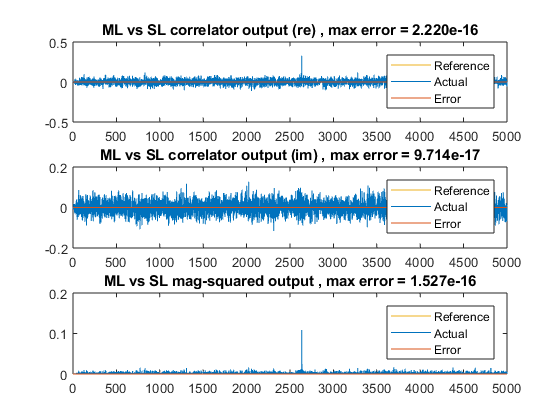


Maximum error for ML vs SL mag-squared output out of 5000 values
 1.526557e-16 (absolute), 1.408724e-13 (percentage)



% Magnitude squared output
MagSqSL = getLogged(slout,'mag_sq_out');
compareData(MagSqOut,MagSqSL,{2 3 3},'ML vs SL mag-squared output');


% Peak value
MidSampleSL = getLogged(slout,'mid_sample');
Detected = getLogged(slout,'detected');
PeakSL = MidSampleSL(Detected>0);

fprintf('\nPeak location = %d, magnitude = %.3d using global max\n',location,peak);


Peak location = 2636, magnitude = 3.292e-01 using global max


fprintf('Peak location = %d, mag-squared = %.3d using local max\n',location_2,peak_2);

Peak location = 2636, mag-squared = 1.084e-01 using local max


fprintf('Peak mag-squared from Simulink = %.3d, error = %.3d\n',PeakSL,abs(peak_2-PeakSL));

Peak mag-squared from Simulink = 1.084e-01, error = 1.527e-16
